## Generating the Sine Wave

clear, close all

% Generate Sine Wave
FFT = 512; 
Fs = 60e6;
Fc = 15e6;
F0 = Fc;        % Desired output frequency (Hz)
Deltaf = 0.05;  % Frequency resolution (Hz)
SFDR = 90;      % Spurious free dynamic range (dB)
Ts = 1/Fs;      % Sample period (s)
phOffd = pi/2;  % Desired phase offset (rad)

N = ceil(log2(1/(Ts*Deltaf))); 
Q = ceil((SFDR - 12)/6);
phIncr = round(F0*2^N*Ts);
phOff = (2^N*phOffd)/(2*pi);
ditherBits = N - Q;



## Low Pass Filter Design

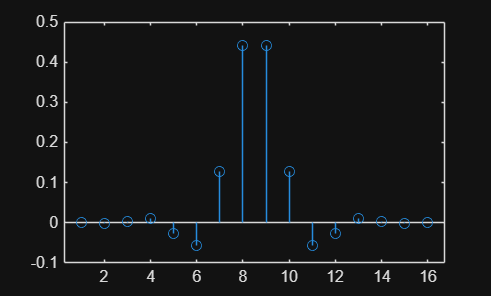

L = 15;         % Filter order -> length = N + 1
Fs = 60e6;
Fc = 15e6;      % Cutoff = Fs/4
Wn = Fc/(Fs/2); % normalized cutoff in (0,1), here 0.5

win = blackman(L+1); 
h = fir1(L, Wn, "low", win, "scale");  % Type I linear-phase lowpass
hf = fi(h,1,12,11);
stem(h)

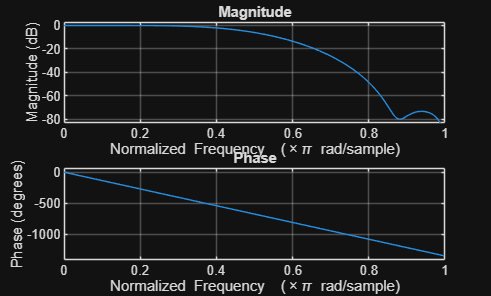

freqz(h)

## Spectral Averaging

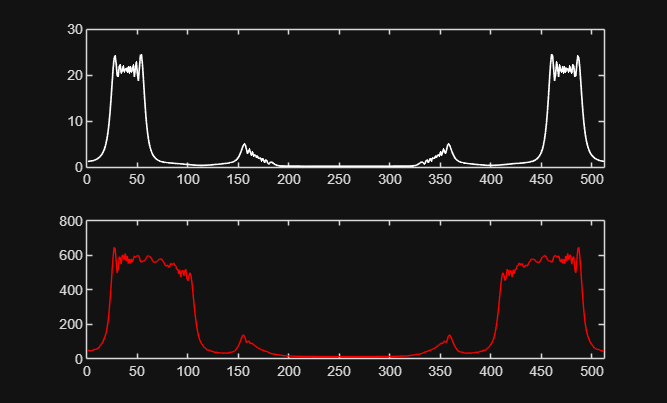

% Look at data to determine at what index is valid = 1
k = find(out.SciInfo_Valid, 1); 
fftData = out.SciInfo(k:end);

% Arrange data in columns with 512 rows according to data size
a = 1:FFT;  
a = a'; 
subplot(2,1,1)
plot(a, fftData(1:FFT), 'w', 'LineWidth',1); 
xlim([0 FFT])

% Number of Spectral Averages
specAvg = floor(length(fftData)/FFT); 
fftData_snr1 = fftData(1:specAvg*FFT); 
fftData_snr2 = reshape(fftData_snr1, FFT, specAvg);

% Sum along the columns 
fftData_snr3 = sum(fftData_snr2, 2);
% hold on
subplot(2,1,2)
plot(a,fftData_snr3, 'r')
xlim([0 FFT])